
$$\begin{array}{l}
\text{ECSE}\text{ }307-\text{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\text{Professor}\text{ }\text{Aditya}\text{ }\text{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\text{TA}:\text{Mohammad}\text{ }\text{Afshari}\text{ }\text{and}\text{ }\text{Anas}\text{ }\text{El}\text{ }\text{Fathi}
\end{array}$$


# 
$$\text{Lab}\text{ }8$$


# 
$$\mathrm{Lead}\text{ }\mathrm{Compensation}$$


%* Fill in your group number----------------------------------------------%
 GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, the objective is to learn the frequency response design methods based on Bode plot. The main idea of frequency based design method is to use the Bode plot of the open-loop transfer function and estimate the closed-loop response. Adding a controller to the system changes the open-loop Bode plot, therefore changing the closed-loop response. 

**1. Problem Statement**

Consider the following open loop transfer function:


$$G_{\mathrm{ol}} \left(s\right)=\frac{280\left(s+0\ldotp 5\right)}{s\left(s+0\ldotp 2\right)\left(s+5\right)\left(s+70\right)}$$


## **1. Bode Plot, Gain Margin, and Phase Margin**

In this section we plot the Bode of given transfer functions and find the values of Gain Margin and Phase Margin of these transfer functions. 

## *Question 1 (1 mark)*

Produce the Bode plot of $G\left(s\right)$. 

% Write your code here
s = tf('s');
Go = (280*(s+0.5))/(s*(s+0.2)*(s+5)*(s+70))


Go =
 
            280 s + 140
  -------------------------------
  s^4 + 75.2 s^3 + 365 s^2 + 70 s
 
Continuous-time transfer function.



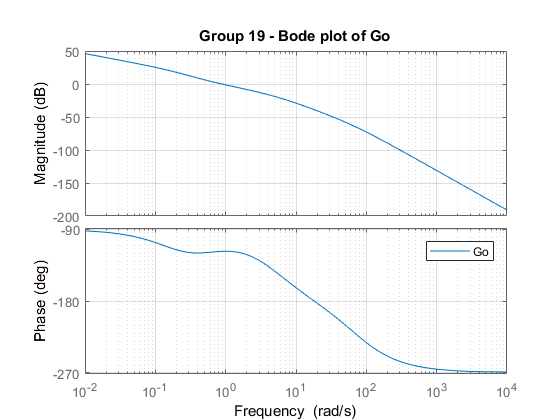


bode(Go)
legend('show')
title(sprintf('Group %d - Bode plot of Go', GroupeNum));
grid on

 In MATLAB, we use `margin `to calculate the minimum gain margin, `Gm`, phase margin, `Pm`, and associated frequencies `Wgm` and `Wpm` of SISO open-loop models. The gain and phase margin of a system `sys` indicates the relative stability of the closed-loop system formed by applying unit negative feedback to `sys`.

The gain margin is the amount of gain increase or decrease required to make the loop gain unity at the frequency `Wgm` where the phase angle is –180° (modulo 360°). In other words, the gain margin is 1/*g* if *g* is the gain at the –180° phase frequency. Similarly, the phase margin is the difference between the phase of the response and –180° when the loop gain is 1.0. The frequency `Wpm` at which the magnitude is 1.0 is called the *unity-gain frequency* or *gain crossover frequency*. 

**Note:** It is generally found that gain margins of three or more combined with phase margins between 30 and 60 degrees result in reasonable trade-offs between bandwidth and stability.

We use this function as follows:

`[Gm,Pm,Wgm,Wpm] = margin(sys)` computes the gain margin `Gm`, the phase margin `Pm`, and the corresponding frequencies `Wgm` and `Wpm`, given the SISO open-loop dynamic system model `sys`. `Wgm` is the frequency where the gain margin is measured, which is a –180 degree phase crossing frequency. `Wpm` is the frequency where the phase margin is measured, which is a 0dB gain crossing frequency. These frequencies are expressed in $\frac{\mathrm{rad}}{\mathrm{time}}$, where $\mathrm{time}$ is the unit specified in the property of `sys`. When `sys` has several crossovers, `margin` returns the smallest gain and phase margins and corresponding frequencies. For more information about `margin(sys)`, use the following code:

doc margin

## *Question 2 (1 mark)*

Find the Gain Margin, Phase Margin and the corresponsing frequencies for $G_{\mathrm{ol}} \left(s\right)$. 

% Write your code here
[Gm,Pm,Wgm,Wpm] = margin(Go) 

Gm = 87.7059

Pm = 62.5034

Wgm = 18.0968

Wpm = 0.8829

***Question 3 (1 mark)***

Based on the values of the GM and PM, determine whether the open loop system is stable or not? What can you say about the stability of the closed loop system? Justify your answer.

***Since both GM and PM are positive, the system is stable.***

## *2. Lead Compensator Design*

Consider $G_{\mathrm{ol}} \left(s\right)$ and $G_{\mathrm{cl}} \left(s\right)$ where $G_{\mathrm{cl}} \left(s\right)$is the unity feedback closed loop transfer function of $G\left(s\right)$ and could be found as follows:


$$G_{\text{cl}} \left(s\right)=\frac{G\left(s\right)}{1+G_{\mathrm{ol}} \left(s\right)}\ldotp$$


We want to design a lead compensator such that the following conditions satisfy for $G_{\mathrm{cl}} \left(s\right)$.

- $\mathrm{Steady}\text{ }\mathrm{State}\text{ }\mathrm{error}\text{ }\mathrm{to}\text{ }a\text{ }\mathrm{ramp}\text{ }\mathrm{input}\le 0\ldotp 02$.

- $\mathrm{Phase}\text{ }\mathrm{Margin}\ge {45}^{\circ }$.

A first order phase-lead compensator has the form given below:


$$G_c \left(s\right)=K\frac{1+\text{Ts}}{1+\alpha \text{Ts}}$$


where $K=K_c \alpha$. The open loop transfer function of the compensated system is 


$$G_{\text{olc}} \left(s\right)=K\frac{1+\text{Ts}}{1+\alpha \text{Ts}}G\left(s\right)$$


The first step is in the design is to provide the required static velocity error constant. Define $G_{1\left(S\right)}$as follows:


$$G_1 \left(s\right)=\mathrm{KG}\left(s\right)\ldotp$$


***Question 4 (1 mark)***

Find the value of $K$such that the static velocity constant condition satisfies. You can use function dcgain`. dcgain `evaluates frequency response at a given frequency.

% the dc gain of the compensator is K. The dc gain of the whole system should be 1 then K is

Kv = dcgain(s*Go)

Kv = 2

K = 50/Kv % where 50 is 1/0.02

K = 25

With this value of $K$, the compensated system will satisfy the steady state requirement. Now we shall plot the Bode plot of $G_1 \left(s\right)$. 

***Question 5 (1 mark)***

Draw the Bode plot of $G_1 \left(s\right)$and $G_{\mathrm{ol}} \left(s\right)$ and find the GM, PM, and corresponding frequencies. Compare the two plots to see the effect of multiplying a constant gain $K$ to the transfer function.

% Write your code here
G1 = K*Go;
bode(G1,Go)
[Gm2,Pm2,Wgm2,Wpm2] = margin(G1) % This is the Gain and Phase margin of K*Go.

Gm2 = 3.5082

Pm2 = 18.6757

Wgm2 = 18.0968

Wpm2 = 9.3553

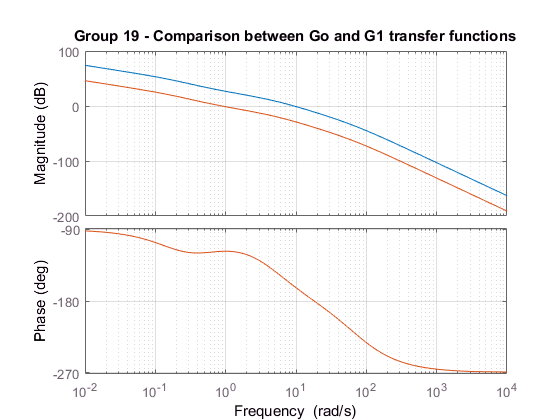



title(sprintf('Group %d - Comparison between Go and G1 transfer functions', GroupeNum));

grid on

The phase-lead compensator will add positive phase to our system over the frequency range $\frac{1}{\alpha T}$ and $\frac{1}{T}$, which are called the corner frequencies.  

## *Question 6 (2 marks)*

Based on the values of the GM and PM and the corresponsidng frequencies you found in Question 5, design the lead compensator that satisfies the cinditions given in this part. Write the final lead compensator as a transfer function.

Hint: `sin()` in MATLAB uses radian as the input argument. For input arguments in degree use `sind()`.

% Write your code here
% doc sind

Pm_offset = 45 - Pm2 + 15

Pm_offset = 41.3243

Alpha = (1 - sind(Pm_offset))/(1+ sind(Pm_offset))

Alpha = 0.2046


x = -20*log10(1/sqrt(Alpha))

x = -6.8912

wm = 1/sqrt(Alpha)

wm = 2.2109


wm = 13.22 % This value is found using the graph above.

wm = 13.2200


T = 1/(sqrt(Alpha)*wm)

T = 0.1672

Gc = K*(1+T*s)/(1+T*s*Alpha)


Gc =
 
  4.181 s + 25
  -------------
  0.03421 s + 1
 
Continuous-time transfer function.



***Question 7 (3 mark)***

1. Produce the Bode diagram of the lead compensator you found in Question 6.

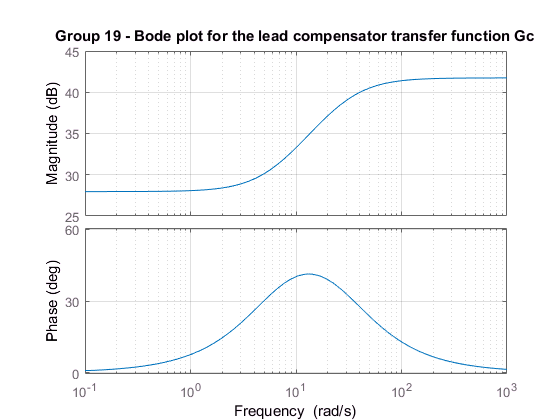

% Write your code here
bode(Gc)
title(sprintf('Group %d - Bode plot for the lead compensator transfer function Gc', GroupeNum));
grid on

2. Write the compensated open loop transfer function $G_{\text{ol}c} \left(s\right)$and produce the Bode diagram of this transfer function. Check whether the specifications are satisfied or not (use `margin` to check the GM and PM). (Produce the Bode of the uncompensated transfer function as well)

% Write your code here

G_olc = Gc*Go


G_olc =
 
                 1171 s^2 + 7585 s + 3500
  ------------------------------------------------------
  0.03421 s^5 + 3.573 s^4 + 87.69 s^3 + 367.4 s^2 + 70 s
 
Continuous-time transfer function.



bode(G_olc,Go)

[Gm3,Pm3,Wgm3,Wpm3] = margin(G_olc)

Gm3 = 5.5548

Pm3 = 46.5137

Wgm3 = 43.8176

Wpm3 = 14.8946

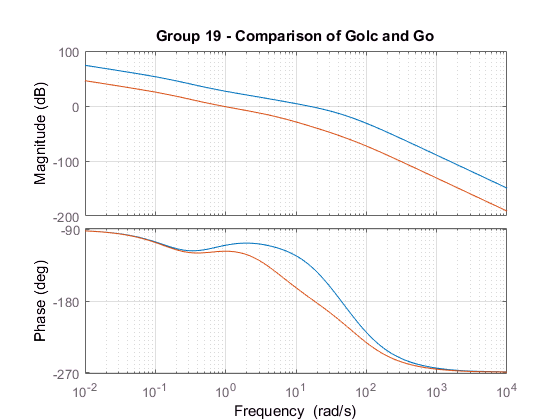

title(sprintf('Group %d - Comparison of Golc and Go', GroupeNum));
grid on

3. Plot the output of both the compensated and uncompemsated closed loop control systems to ramp input and check whether the specifications for the steady state error is satisfied or not? 

% Write your answer here
Gc_loop = feedback(G_olc,1)


Gc_loop =
 
                     1171 s^2 + 7585 s + 3500
  --------------------------------------------------------------
  0.03421 s^5 + 3.573 s^4 + 87.69 s^3 + 1538 s^2 + 7655 s + 3500
 
Continuous-time transfer function.




Go_loop = feedback (Go,1) 


Go_loop =
 
               280 s + 140
  --------------------------------------
  s^4 + 75.2 s^3 + 365 s^2 + 350 s + 140
 
Continuous-time transfer function.



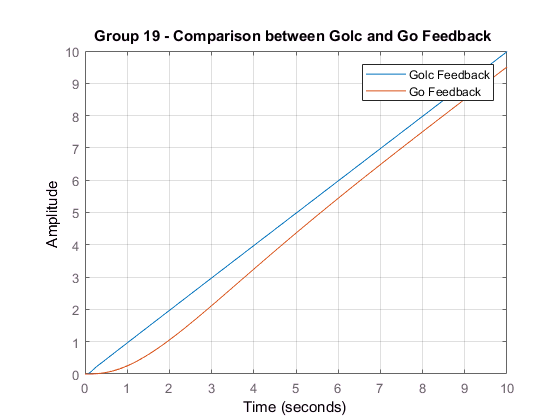

step(Gc_loop/s) % ramp of G_olc Feedback
hold on;
step(Go_loop/s) % ramp of G_o Feedback
title(sprintf('Group %d - Comparison between Golc and Go Feedback ', GroupeNum));
legend('Golc Feedback','Go Feedback')
xlim([0 10])
grid on